# A method of reducing the boundary value problem for ODEs to the Cauchy problem (shooting method)

## Taks 1

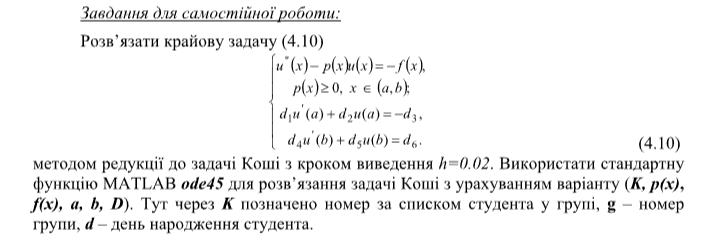

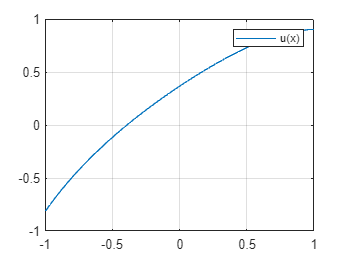

h = 0.02;

a = -1; b = 1; n = 51;
D = [1, 1, 1, 1, 17, 1];

[X, U] = shootingMethod(a, b, n, D);

plot(X, U(:,1));
legend("u(x)");
grid on;



export("Computational methods/Lab5.mlx")

ans = 'E:\Work\Applied math\Matlab\Lab5.pdf'

function result = A(x)
    p = @(x)(acos(x));
    result = [0, 1; p(x), 0]; 
end 


function result = F(x)
    f = @(x)(1 + x .* sin(1 + x^2));
    result = [0; f(x)]; 
end 


function result = WS(t, y) 
    result = A(t) * y; 
end 

function result = VS(t, y) 
    result = A(t) * y - F(t); 
end 

function [X, U] = shootingMethod(x0, xn, n, D)
    X = linspace(x0, xn, n);    
    
    % Розв'язок однорiдної системи ЗДР
    u0 = [1; -D(1) ./ D(2)]; 
    U0(1, :) = u0; 
    y1 = u0; n = length(X); 
    for i = 2 : n 
        [~, y] = ode45(@WS, [X(i-1) X(i)], y1); 
        y1 = y(length(y), :); U0(i, :) = y1; 
    end 
    
    
    % Розв'язок неоднорiдної системи ЗДР 
    u0 = [0; D(3) ./ D(2)]; 
    U1(1, :) = u0; 
    y1 = u0; 
    for i=2 : n 
        [~, y] = ode45(@VS, [X(i-1) X(i)], y1); 
        y1 = y(length(y), :); U1(i, :) = y1; 
    end 
    
    
    % обчислення параметра c 
    c = D(4) .* U0(n,1) + D(5) .* U0(n,2); 
    c = (D(6) - D(4) .* U1(n, 1) - D(5) .* U1(n, 2)) ./ c; 
    % знаходження розв'язку в точках виведення 
    U = U1 + c.*U0; 
end